# 'coneplot' method usage example

Common setup for all examples

ex_setup

Setup complete


#### Start timer


tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);


#### Scene

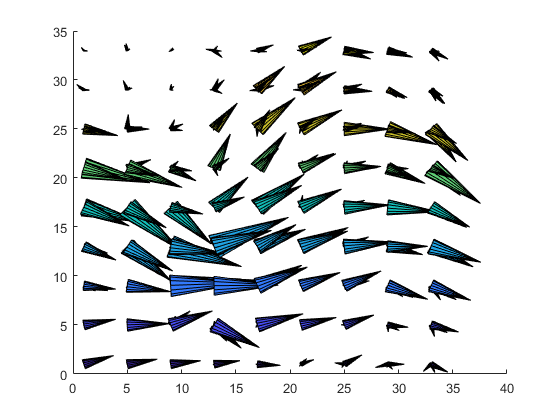

pl.scene_begin('scene_file', 'coneplot.pov', 'image_file', 'coneplot.png');
    pl.include("shapes");
    pl.include("glass");
        
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 50, 'location', [30 50 15], 'look_at', [9 0 1]);
    
    % Lights
    pl.light('location', [30 50 15],  'color', [8 8 8], 'shadowless', true);
    pl.light('location', [0 0 0],     'color', [40 60 20], 'shadowless', true);
    
    % Wind for streams
    load wind u v w x y z
    [m,n,p] = size(u);
    
    % Bounding box
    tex =  pl.declare("tex", pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.2 0.2 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    pl.wire_box('llf_corner', [0 0 0], 'urb_corner', [m n p], 'radius', 0.15, 'texture', tex);
    
    % Coneplot
    [Cx, Cy, Cz] = meshgrid(1:4:m,1:4:n,1:4:p);
    cp = coneplot(u,v,w,Cx,Cy,Cz,y,5);

    pl.coneplot('data', cp);

pl.scene_end();

#### Render and display

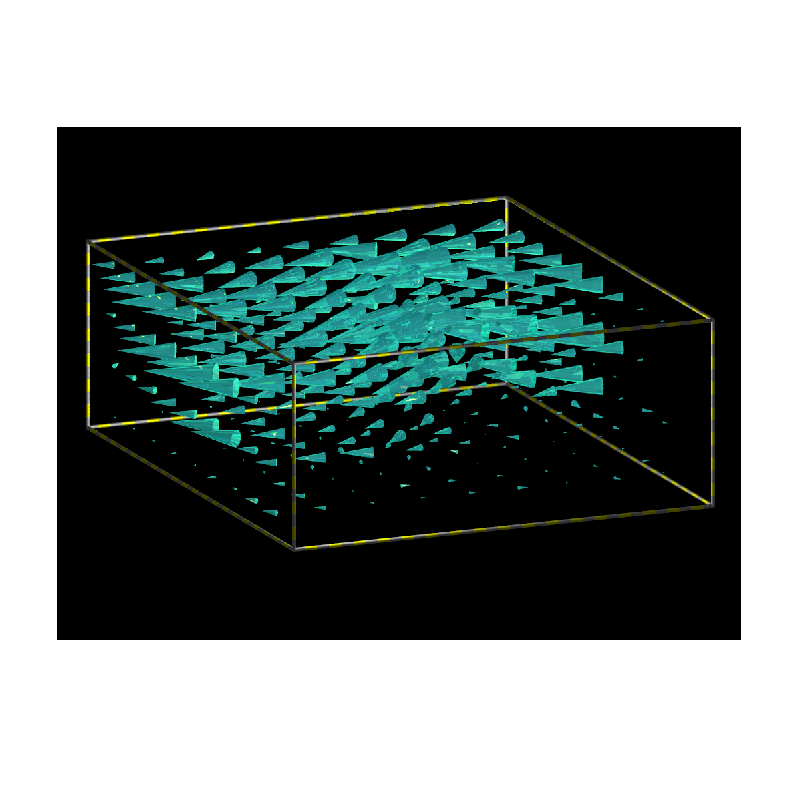

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 7.871462 seconds.
